# Examples for using the `fixed_point_iteration` function.

Copyright © 2021 Tamas Kis

## Example #1: Fixed point of a simple function.

*Find the fixed point of *$f\left(x\right)=\sqrt{x}$.

Defining $f\left(x\right)$,

f = @(x) sqrt(x);

To demonstrate the fact that, for this specific function, the fixed point iteration can converge even with an initial guess very far from the true fixed point, we use an initial guess of $x_0 ={10}^{10}$ 

c = fixed_point_iteration(f,10^10)

c = 1.0000

## Example #2: Plot of intermediate fixed point estimates.

*In example #1, we found the fixed point of *$f\left(x\right)=\sqrt{x}$* using fixed point iteration with an initial guess of *$x_0 ={10}^{10}$*. Now, produce a plot of the intermediate fixed point estimates obtained by the fixed point iteration before it returned the converged fixed point, this time using an initial guess of *$x_0 =100$.

First, we define $f\left(x\right)$ in MATLAB like before.

f = @(x) sqrt(x);

To obtain the intermediate fixed estimates, we simply need to call the `fixed_point_iteration` function with the optional input `'all'`.

intermediate_c = fixed_point_iteration(f,100,[],[],'all');

Plotting the intermediate root estimates,

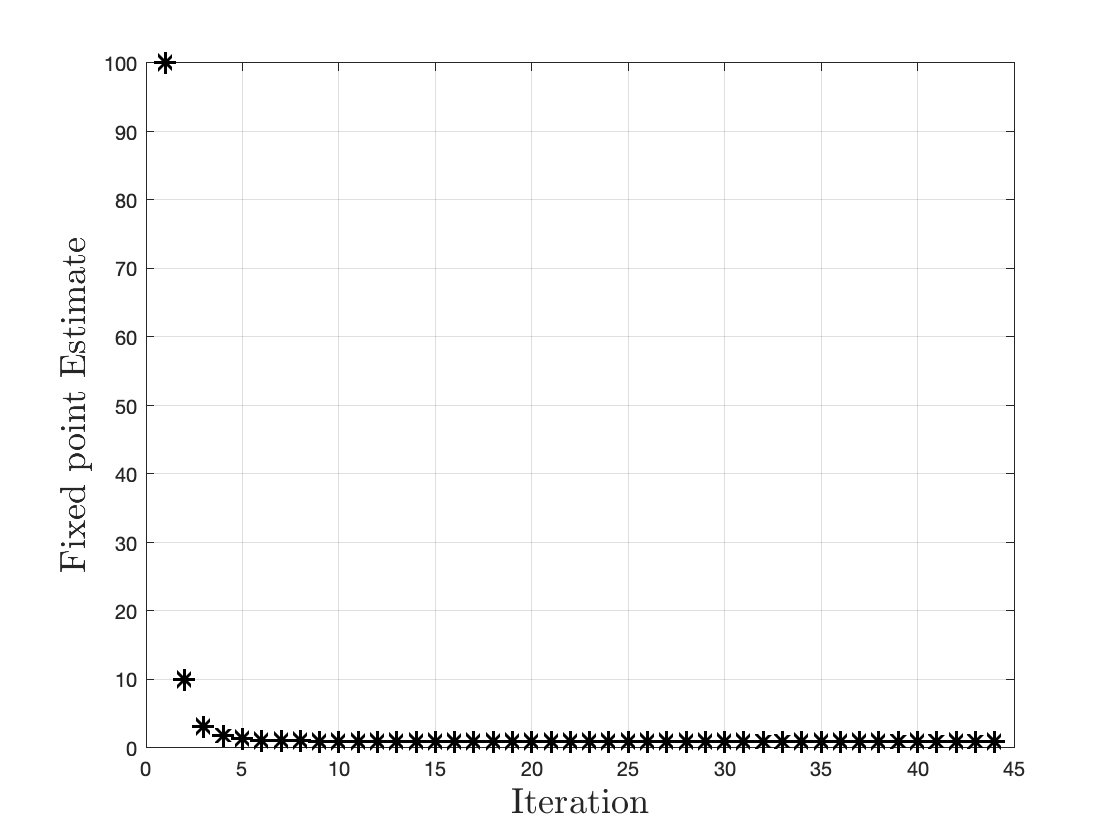

figure;
plot(intermediate_c,'k*','markersize',9,'linewidth',1.5);
grid on;
xlabel('Iteration','interpreter','latex','fontsize',18);
ylabel('Fixed point Estimate','interpreter','latex','fontsize',18);

We can also extract the converged fixed point from `intermediate_c`.

c = intermediate_c(end)

c = 1.0000

## Example #3: Newton's method via fixed-point iteration.

*Use fixed-point iteration to find the root of *$f\left(x\right)=x^2 -1$ in the interval $\left\lbrack 0,\infty \right)$.

Applying fixed-point iteration directly would find the fixed point of $f\left(x\right)$, not its root. However, we can define a function $g\left(x\right)$ that will allow us to use fixed-point iteration to find the root of $f\left(x\right)$:


$$g\left(x\right)=x-\frac{f\left(x\right)}{\;f^{\prime } \left(x\right)}$$


*See Section 1.2 of "DOCUMENTATION.pdf" (included with download or available online at *[https://github.com/tamaskis/fixed_point_iteration-MATLAB/blob/main/DOCUMENTATION.pdf](https://github.com/tamaskis/fixed_point_iteration-MATLAB/blob/main/DOCUMENTATION.pdf)* for why this works).*

Substituting $f\left(x\right)$ and its derivative ($f^{\prime } \left(x\right)=2x$) into $g\left(x\right)$,


$$g\left(x\right)=x-\frac{x^2 -1}{\;2x}=\frac{2x^2 -\left(x^2 -1\right)}{2x}=\frac{x^2 +1}{2x}$$


Defining $g\left(x\right)$ in MATLAB,

g = @(x) (x^2+1)/(2*x);

Since we want the positive root of $f\left(x\right)=x^2 -1$, we pick an initial guess $x=5$. Finding the positive root of $f\left(x\right)$ by finding the fixed point of $g\left(x\right)$,

root = fixed_point_iteration(g,5)

root = 1

## Example #4a: Pipe flow problem (simple solution).

*Consider a pipe flow problem where the velocity of the fluid, *$V$*, is a function of the friction factor, *$f$*.*


$$V=\sqrt{\frac{3000}{700f+10}}\;\textrm{ft}/\mathrm{s}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)$$


*The Reynolds number, *$\textrm{Re}$*, is dependent on the velocity as*


$$\textrm{Re}=600000V\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\right)$$


*Finally, *$f$* is a function of *$\textrm{Re}$* (assuming a smooth pipe).*


$$\frac{1}{\sqrt{f}}=-1\ldotp 8\;\log_{10} \left(\frac{6\ldotp 9}{\textrm{Re}}\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\right)$$


*Find the velocity of the flow through the pipe.*

Let's begin by solving Eq. (3) for $f$.


$$f={\left\lbrack -1\ldotp 8\;\log_{10} \left(\frac{6\ldotp 9}{\textrm{Re}}\right)\right\rbrack }^{-2} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(4\right)$$


Equations (1), (2), and (4) must be satisfied simultaneously, but we cannot solve them simultaneously with algebraic means. However, note that we can form a calculation procedure that maps $V$ to itself:

- From Eq. (1), we can get $V$ from $f$.

- From Eq. (3), we can get $f$ from $\textrm{Re}$.

- From Eq. (2), we can get $\textrm{Re}$ from $V$

This calculation procedure essentially gives us a function $V=g\left(V\right)$:


$$g:V\to \textrm{Re}\to f\to V$$


Therefore, the flow velocity $V$ is simply the fixed point of $g\left(V\right)$ (since $g$ maps $V$ to itself).

We *could* use function composition to define $g\left(V\right)$ using a single expression (in fact, this is exactly what we do in Example #4b below). However, it is quicker/easier to define a *computational* function that evaluates $g\left(V\right)$ in a *sequential *fashion. **We define **$g\left(V\right)$** as the MATLAB function **`g_func`** at the bottom of this page under the "**`g_func`** Function for Example #3" section.** To define $g\left(V\right)$ as an anonymous function, we assign it a function handle:

g = @(V) g_func(V);

Solving for $V$ using an initial guess of $V_0 =1\;\textrm{ft}/\mathrm{s}$,

V = fixed_point_iteration(g,1)

V = 13.7583

## Example #4b: Pipe flow problem (long solution).

*Consider a pipe flow problem where the velocity of the fluid, *$V$*, is a function of the friction factor, *$f$*.*


$$V=\sqrt{\frac{3000}{700f+10}}\;\textrm{ft}/\mathrm{s}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)$$


*The Reynolds number, *$\textrm{Re}$*, is dependent on the velocity as*


$$\textrm{Re}=600000V\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\right)$$


*Finally, *$f$* is a function of *$\textrm{Re}$* (assuming a smooth pipe).*


$$\frac{1}{\sqrt{f}}=-1\ldotp 8\;\log_{10} \left(\frac{6\ldotp 9}{\textrm{Re}}\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\right)$$


*Find the velocity of the flow through the pipe.*

While we have three equations in three unknowns, we cannot solve this system of equations algebraically due to the nonlinearities in the equations for $V$ and $f^{-1/2}$. Let's begin by solving Eq. (3) for $f$.


$$f={\left\lbrack -1\ldotp 8\;\log_{10} \left(\frac{6\ldotp 9}{\textrm{Re}}\right)\right\rbrack }^{-2} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(4\right)$$


Now, we can think of Eqs. (1), (2), and (4) in the following way:


$$V=\phi_1 \left(f\right)$$



$$\textrm{Re}=\phi_2 \left(V\right)$$



$$f=\phi_3 \left(\textrm{Re}\right)$$


We know we can use fixed-point iteration to find the fixed point $x=c$ of a function $f\left(x\right)$ (i.e. $f\left(c\right)=c$). Therefore, our goal is to develop a function where both the input and output are $V$. Then, we can use fixed-point iteration to solve for $V$. Since we can get $V$ from $f$, get $f$ from $\textrm{Re}$, and get $\textrm{Re}$ from $V$ (i.e. $V\to \textrm{Re}\to f\to V$), we could determine such a function using function composition:


$$V=\phi_1 \left(\phi_3 \left(\phi_2 \left(V\right)\right)\right)$$


Mathematically, this involves substituting Eq. (2) into Eq. (4), and substituting the result into Eq. (1).


$$f={\left\lbrack -1\ldotp 8\;\log_{10} \left(\frac{6\ldotp 9}{600000V}\right)\right\rbrack }^{-2} \;\;\;\;\to \;\;\;V=\sqrt{\frac{3000}{700{\left\lbrack -1\ldotp 8\;\log_{10} \left(\frac{6\ldotp 9}{600000V}\right)\right\rbrack }^{-2} +10}}$$


Now, let's define the function $g\left(V\right)$ as the right hand side of the equatioin above for $V$.


$$g\left(V\right)=\sqrt{\frac{3000}{700{\left\lbrack -1\ldotp 8\;\log_{10} \left(\frac{6\ldotp 9}{600000V}\right)\right\rbrack }^{-2} +10}}$$


Then the velocity of the flow through the pipe, $V$, is simply the fixed point of $g\left(V\right)$. Defining $g\left(V\right)$ in MATLAB,

g = @(V) sqrt(3000/(700*(-1.8*log10(6.9/(600000*V)))^(-2)+10));

Obtaining the flow velocity by finding the fixed point of $g\left(V\right)$, using an initial guess of $V_0 =1\;\textrm{ft}/\mathrm{s}$,

V = fixed_point_iteration(g,1)

V = 13.7583

*Clearly, this method is more difficult than that presented in Example #4a, even for such a simple problem. *

## `g_func` Function for Example #4a

function V = g_func(V)
    Re = 600000*V;
    f = (-1.8*log10(6.9./Re)).^(-2);
    V = sqrt(3000./(700*f+10));
end